# Call Python from MATLAB

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

Check that MATLAB can recognize the Python installation. Use `pyversion` if you are using a MATLAB version prior to R2019b.

% pyversion()
pyenv

ans =   PythonEnvironment with properties:

          Version: "3.8"
       Executable: "C:\Users\mgavilan\AppData\Local\Programs\Python\Python38\python.EXE"
          Library: "C:\Users\mgavilan\AppData\Local\Programs\Python\Python38\python38.dll"
             Home: "C:\Users\mgavilan\AppData\Local\Programs\Python\Python38"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "15228"
      ProcessName: "MATLAB"


Test a simple function.

py.math.sqrt(42)

Pass arguments using pyargs.

% py.textwrap.wrap("Hello world!",pyargs('width',2))   % errors
py.textwrap.wrap("Hello world!",pyargs('width',int8(2)))

## Read weather data using Python module 

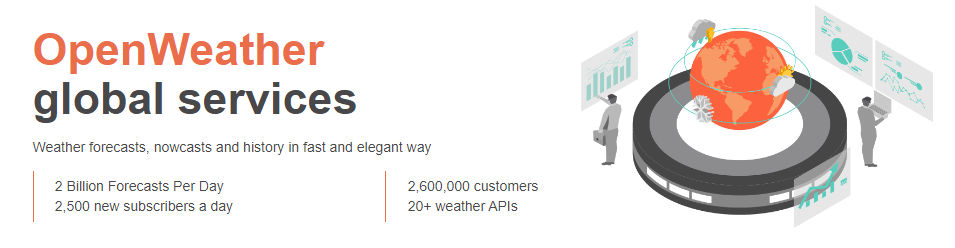

The weather.py module reads and parses current weather data from the web API: [https://openweathermap.org/api](https://openweathermap.org/api)

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

Use the weather.py module to get the air quality for Boston. This is a user-defined Python module which includes functions to read and parse the current and forecasted weather data by location.

jsonData = py.weather.get_current_weather("Natick","US",apikey.Key)

jsonData =   Python dict with no properties.

    {'coord': {'lon': -71.3495, 'lat': 42.2834}, 'weather': [{'id': 800, 'main': 'Clear', 'description': 'clear sky', 'icon': '01n'}], 'base': 'stations', 'main': {'temp': 50.92, 'feels_like': 48.96, 'temp_min': 45.1, 'temp_max': 54.79, 'pressure': 997, 'humidity': 69}, 'visibility': 10000, 'wind': {'speed': 3.44, 'deg': 170}, 'clouds': {'all': 0}, 'dt': 1648255228, 'sys': {'type': 2, 'id': 2005486, 'country': 'US', 'sunrise': 1648204799, 'sunset': 1648249355}, 'timezone': -14400, 'id': 4944994, 'name': 'Natick', 'cod': 200}


Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 50.92, 'feels_like': 48.96, 'temp_min': 45.1, 'temp_max': 54.79, 'pressure': 997, 'humidity': 69, 'speed': 3.44, 'deg': 170, 'lon': -71.3495, 'lat': 42.2834, 'city': 'Natick', 'current_time': '2022-03-25 20:40:36.110385'}


## Preprocess data 

The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

data = struct with fields:
            temp: 50.9200
      feels_like: 48.9600
        temp_min: 45.1000
        temp_max: 54.7900
        pressure: [1×1 py.int]
        humidity: [1×1 py.int]
           speed: 3.4400
             deg: [1×1 py.int]
             lon: -71.3495
             lat: 42.2834
            city: [1×6 py.str]
    current_time: [1×26 py.str]


Convert the remaining python types to the desired MATLAB data types.

double(data.pressure)

ans = 997

Perform the remaining conversions using the function below. 

convertData(data)

#### Obtain values from weather station

% readChannelID = 12397;
% tempWeatherStation = thingSpeakRead(readChannelID,"Fields",4)

tempWeatherStation = 53.1000

#### Display on a map using Mapping Toolbox

% %wmmarker(data.lat,data.lon)
% description_map = "OpenWeather = "+num2str(data.temp)+"°F;"+ '  ' +"WeatherStation = "+num2str(tempWeatherStation)+"°F";
% wmmarker(data.lat,data.lon,"OverlayName","Temperatures","Description",description_map)

## Handle timeseries with the weather forecast

Now let's look at the weather forecast for this week in Boston!

jsonData = py.weather.get_forecast("Boston","US",apikey.Key);
forecastData = py.weather.parse_forecast_json(jsonData);
forecast = struct(forecastData)

The type of data returned by the parsed forecast date is a **Python list**:

forecast.temp

It can be converted to a matrix of doubles:

% tempForecast = double(forecast.temp)          % from an array
tempForecast = cell2mat(cell(forecast.temp))    % from a list

Transform **timestamp list** from Python in **MATLAB datetime**:

foreTime = cell(forecast.current_time)
T = cellfun(@string,foreTime)

Convert T in datetime

time = datetime(T)

plot(time,tempForecast)
xtickangle(45)

## Preprocess data using MATLAB live task

Weather forecasts are only provided every 4 hours. We want to retime to have data interpolated every single hour.

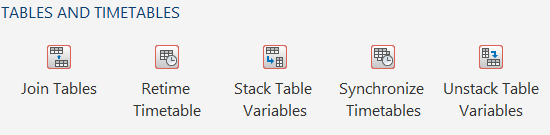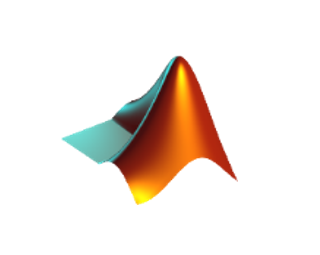

foreTemp = timetable(time',tempForecast','VariableNames',{'Temperature'})

% Retime timetable
newTimetable = retime(foreTemp,'regular','spline','TimeStep',hours(1))

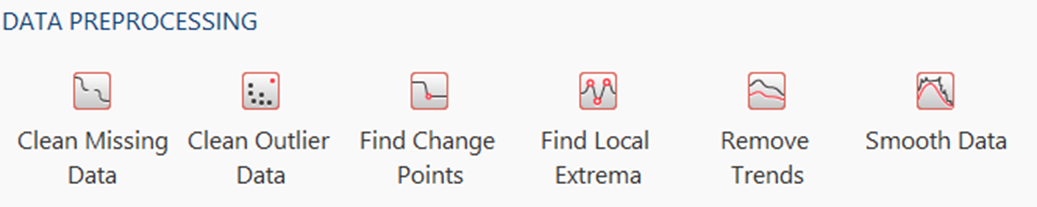

% Remove trend from data
detrendedData = detrend(tempForecast);

% Display results
clf
plot(tempForecast,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(detrendedData,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Detrended data')
plot(tempForecast-detrendedData,'Color',[217 83 25]/255,'LineWidth',1,...
    'DisplayName','Trend')
hold off
legend

## Predict air quality

The machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file for use in production. 

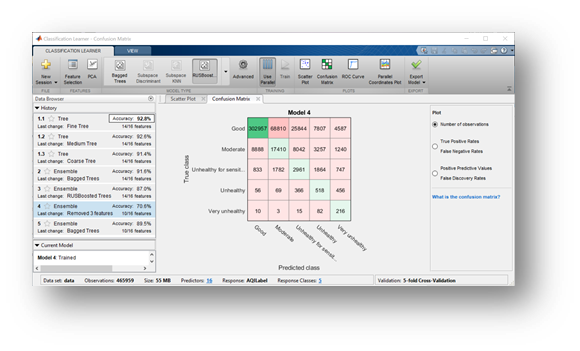

Use a function (`prepData.m`) to convert and prepare data for machine learning (create a table with the expected variable names, preprocessing steps, etc). 

currentData = prepData(weatherData)

Use the model to predict the air quality for the new weather data.

'*airQualModel.mat*' is a pre-trained Bagged Classification Tree/ "Random Forest" classification network. The network was trained using a large data set stored on a local HDFS cluster (~1TB of historical weather data) and required the use of the "tall" MATLAB datatype.  The model was saved as a *.mat file for use in predicting air quality in this demonstration. 

load airQualModel 

airQual = predict(model,currentData)

## Share prediction code

Create a function with these steps to be called in the Python environment.

edit("predictAirQual.m")

See `CallMATLABfromPython.ipynb`

## Reload Python module

Reload *weather.py *after modifications:

clear classes
mod = py.importlib.import_module('weather'); 
py.importlib.reload(mod); 

Read the documentation to know more:

[Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/releases/R2015b/matlab/matlab_external/call-modified-python-module.html)

**Helper Functions**

function data = convertData(data)
% Organize and convert data types 
data = struct2table(data);
% Check for wind direction (deg), sometimes missing
if ~any(data.Properties.VariableNames == "deg")
    deg = "";
    data = addvars(data,deg,'After','speed');
end
data = removevars(data,["temp_min","temp_max"]);
data.Properties.VariableNames([1:5,end]) = ["T","P","RH","WindSpd","WindDir","DateLocal"];
data = convertvars(data,["T","P","RH","WindSpd","WindDir"],"double");
data = convertvars(data,["city","DateLocal"],"string");

% Convert date
if strlength(data.DateLocal) > 20
    data.DateLocal = datetime(data.DateLocal,"InputFormat","uuuu-MM-dd HH:mm:ss.SSS");
else
    data.DateLocal = datetime(data.DateLocal);
end

end

Subsequential calls of the `weather.py` functions in a single MATLAB function:

function [time,tempForecast] = callWeatherFromPython(city,apikey)
    switch city
        case "Boston" 
            country = "US";
        case "Paris"
            country = "France";
        case "Moscow"
            country = "Russia";
    end
    jsonData = py.weather.get_forecast(city,country,apikey);
    forecastData = py.weather.parse_forecast_json(jsonData);
    forecast = struct(forecastData);
    tempForecast = double(forecast.temp);
    foreTime = cell(forecast.current_time);
    T = cellfun(@string,foreTime);
    time = datetime(T);
end